# Main code

clear all
close all
clc

addpath("plots")
addpath("measurements")

## Data

In this session we define the basic variables of our system

#### Global variables

global m g R1 lfe Afe m0 mu_r mu x0 N R2 rho diameter
% units: kg, m, A, V, H/m, Ohm in the IS convention

[m,g,R2,m0,lfe,x0,Afe,mu_r,mu,N,theta_fe,rho,diameter] = data_variables();

#### Estimation of windings

S = pi*((diameter/2)^2); %section of wire
l = R2*S/rho; %length of the wire
D_coil = 0.0616; %diameter of the coils
C_coil = 2*pi*(D_coil/2); %circunference coil
N_estimated = l/(2*C_coil);

clear S l D_coil C_coil

The real number of windings and the estimated one are:

N_estimated , N

N_estimated = 482.3023

N = 860

#### Equilibrium points

*Experimentally*

x_eq = [0.019 0.0175 0.016 0.0145 0.0135 0.012 0.011 0.01 0.00975];
I_eq = [1.5 1.75 2 2.25 2.5 2.75 3 3.25 3.5];

*Using the ideal model*

for i = 1:length(x_eq)
    L_ideal = (N^2)/(theta_fe+2*(x_eq(i)/(m0*Afe))); 
    I_ideal(i) = (sqrt(9.81*(N^2)*Afe*m0*m))/L_ideal;
end

*Plots*

% linear_int_reg_Eq(x_eq,I_eq)
% linear_int_reg_Eq_ideal(x_eq,I_ideal)

## Electrical model characterisation

#### Computation of R with the real model

I_test = [1.9 2.15 2.4 2.65 2.95 3.2 3.4 3.65 3.88];
V_test = [7 8 9 10 11 12 13 14 15];

R1_t = 0;

for i = 1:length(I_test)
    R1_t = [R1_t,V_test(i)/I_test(i)];
    R1 = mean(R1_t(2:end));
end

*Plots*

% linear_int_reg_R1(I_test,V_test)

#### Computation of tau's

The tau's were measured using the PoliArd Board. The experiments use a full stairs of steps from 0V to 15V and vice versa.

P.S. Measurements made with volt values of 1,2 and 3 are discarded due to the effect of measurement noise

pos_test_exp = [0.025 0.0236 0.0227 0.0216 0.0198 0.0183 0.0176 0.0165 0.0153 0.0145 0.0135 0.0125 0.0113 0.0105 0.0097 0.0085];
positions = 0.028 - pos_test_exp;

**Unload test for tau's**

[tau_up, currents_up, tau_down, currents_down] = get_tau_both();
tau_up = tau_up((4:15),:);
currents_up = currents_up(4:15);

*Computation of Ld*

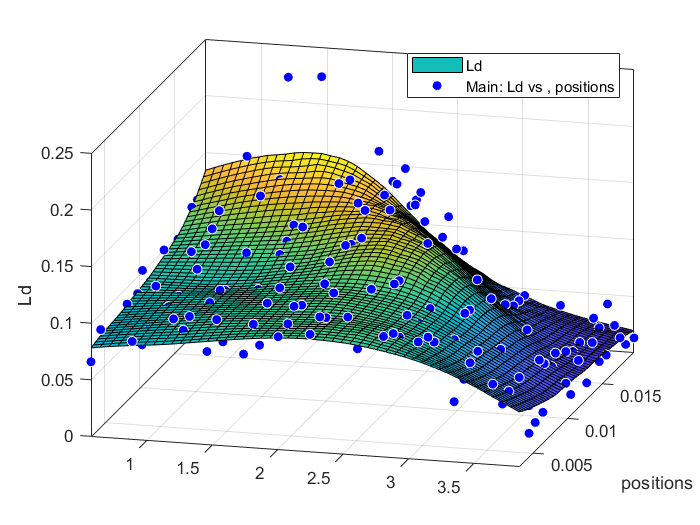

Ld_up = tau_up*R1;
Ld_down = tau_down*R1;

%flip the order of the "down" values
currents_down = flip(currents_down(1:end-1));
Ld_down = flip(Ld_down, 1);
tau_down = flip(tau_down, 1);

% Weigthed mean value of the Ld - tau - currents
Ld = (2*Ld_down(1:end-1,:) + Ld_up)/3;
tau = (2*tau_down(1:end-1,:) + tau_up)/3;
Ld = [Ld; Ld_down(13,:)];
tau = [tau; tau_down(13,:)];
currents = (currents_up + currents_down(1:end-1,:))/2;
currents = [currents ; currents_down(end)];

% Means of current - fitting
[Ld_function, ~] = createfit3D(currents', positions, Ld,'LowessFit', 0.22 , [15.0, 22.7]);

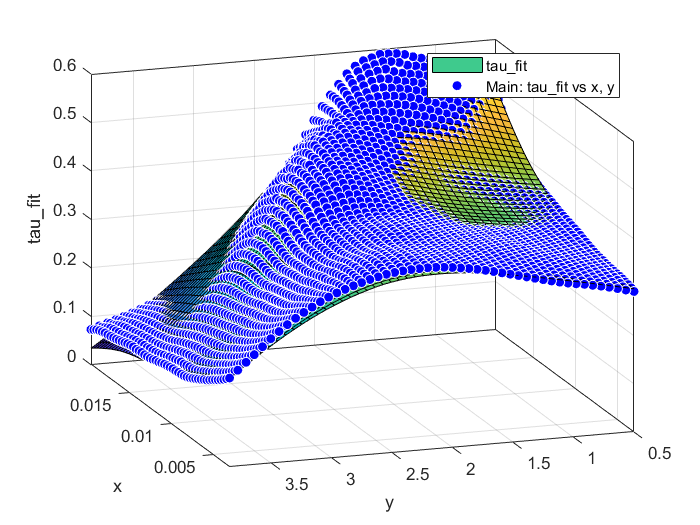

y = linspace(0.5,3.85,50); %currents
x = linspace(0.003,0.0195,50); %positions

for i = 1:length(y)
    for j = 1:length(x)
        Ld_fit(i,j) = Ld_function(y(i),x(j));
    end
end
tau_fit = Ld_fit*R1;

[tau_function, ~] = createfit3D(x, y, tau_fit, 'None', 0.25, [-108.9, 20.4 ]);

*Computation of L using ODE45*

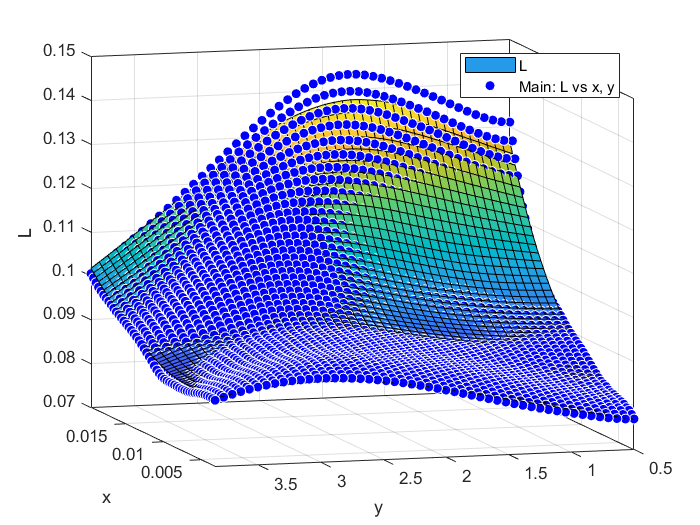

for i = 1 : length(Ld_fit)
    
    Ld_function_test = fit(y',Ld_fit(:,i),'spline');
    [I,L(:,i)] = ode45(@(I,L1) (Ld_function_test(I)-L1)/I,y,Ld_fit(1,i));

end

[L_function, ~] = createfit3D(x, y, L,'None', 0.25 , [-106.5, 10.0]);

Non so cosa sia - Caclolo delle derivate di L 

Abbiamo preso approx corrente a valore più piccolo dove Ld è simile a L perchè qua serve valore iniziale (uguale a vecchio paper)

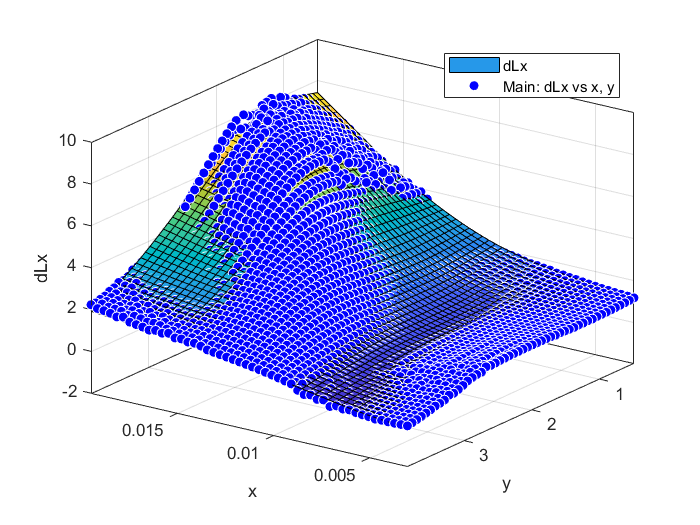

f = [-2523; 3096; -115.8; 1.131; 78.15; -.7173; 4513; -107.2; .6886; 12770; -695.4; 7.044];

L_function1 = @(x,y)  (f(1)*x^2+f(2)*x^1+f(3))*atan((f(4)*x^2+f(5)*x^1+f(6))*y+(f(7)*x^2+f(8)*x^1+f(9)))+f(10)*x^2+f(11)*x^1+f(12);

[xx, yy] = meshgrid( x, y );
[dLx, dLy] = differentiate(L_function,xx,yy);

[dLx_function, ~] = createfit3D(x, y, dLx,'None',0.25,[-144.4,26.8]);

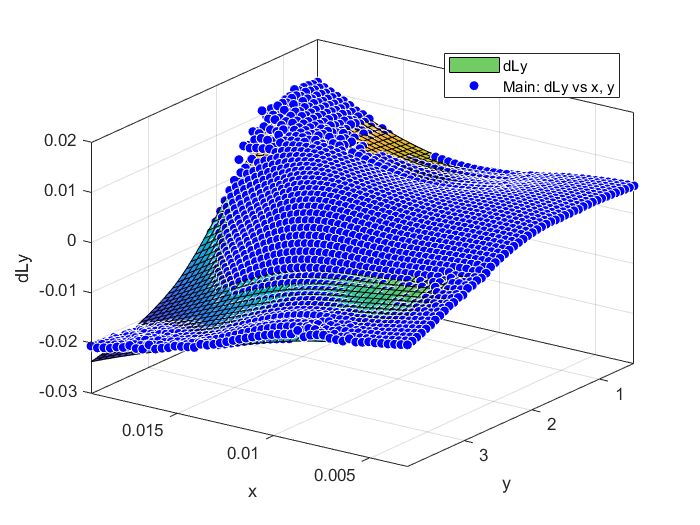

[dLy_function, ~] = createfit3D(x, y, dLy,'None',0.25,[-144.4,26.8]);

## Mechanical model characterisation

#### Computation of K

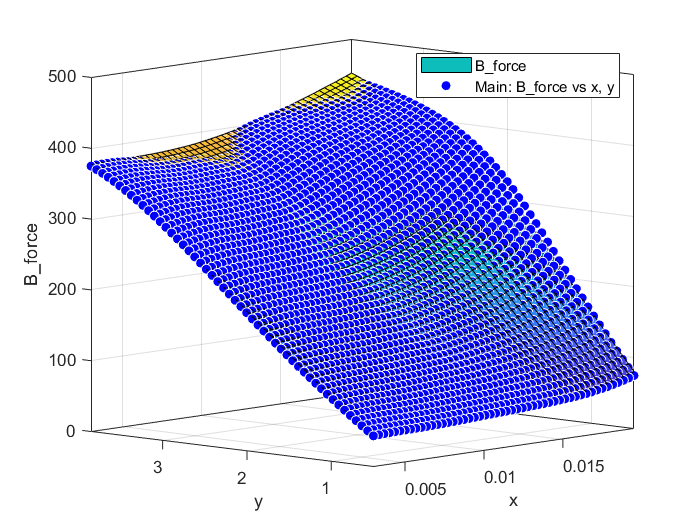

F_peso = g*m;

B_force = (L.*repmat(y',1,size(L,2)))/Afe;
[B_force_function, ~] = createfit3D(x, y, B_force,'LowessFit',0.3,[-47.3,8.4]);

*Definition of K in function of x*

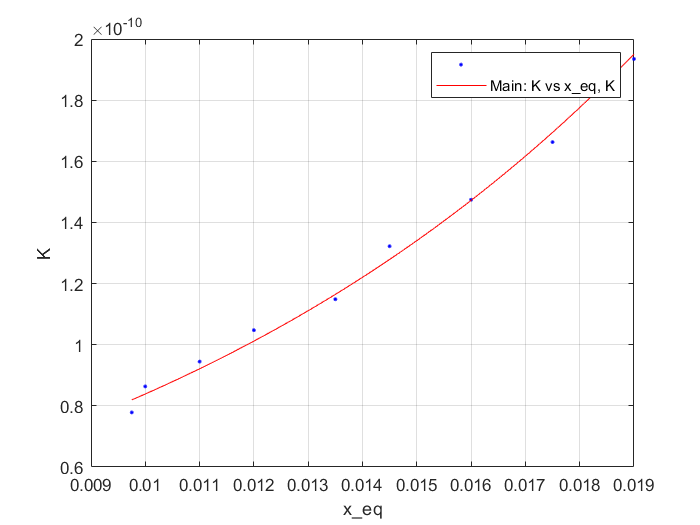

for i = 1:length(I_eq)
    K(i) = F_peso*m0/((B_force_function(x_eq(i),I_eq(i)))^2);
end
[K_function, ~] = createfit2D(x_eq, K,'NonlinearLeastSquares',[3.07989491972634e-09 93.7382856499099]);

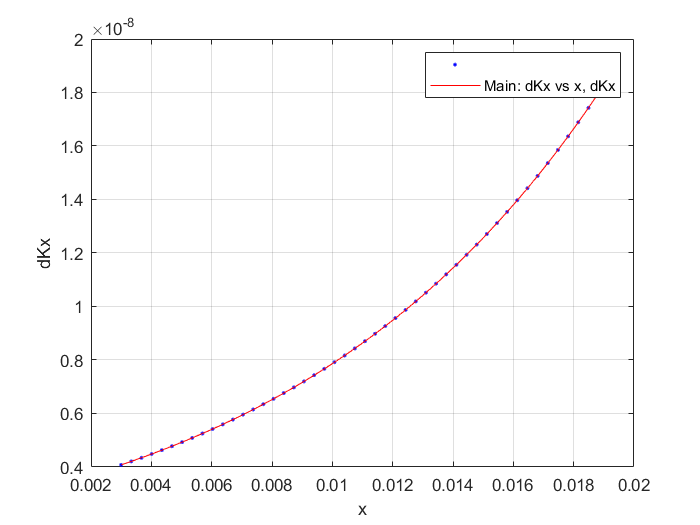



K = K_function(x);
dKx = differentiate(K_function,x);

[dKx_function, ~] = createfit2D(x, dKx,'NonlinearLeastSquares',[3.29288489402281e-11 93.7382856499101]);

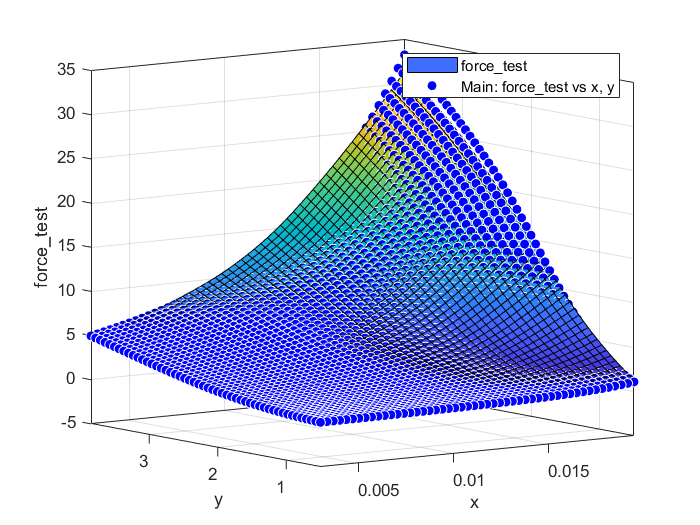


for i = 1:length(x)
    for j = 1:length(y)
        force_test(j,i)=K_function(x(i))*(B_force_function(x(i),y(j))^2)/m0;
    end
end

[force_function, ~] = createfit3D(x, y, force_test,'LowessFit',0.3,[-36.2,8.6]);

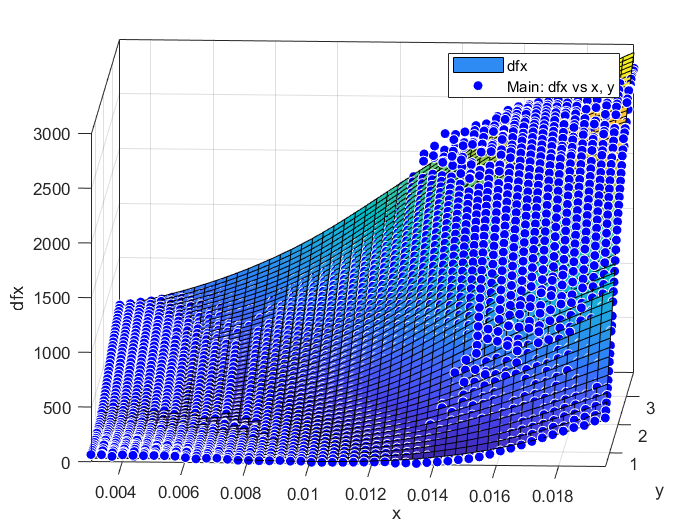

[dfx, dfy] = differentiate(force_function,xx,yy);
[dfx_function, ~] = createfit3D(x, y, dfx,'None',0.25,[3.2,16.1]);

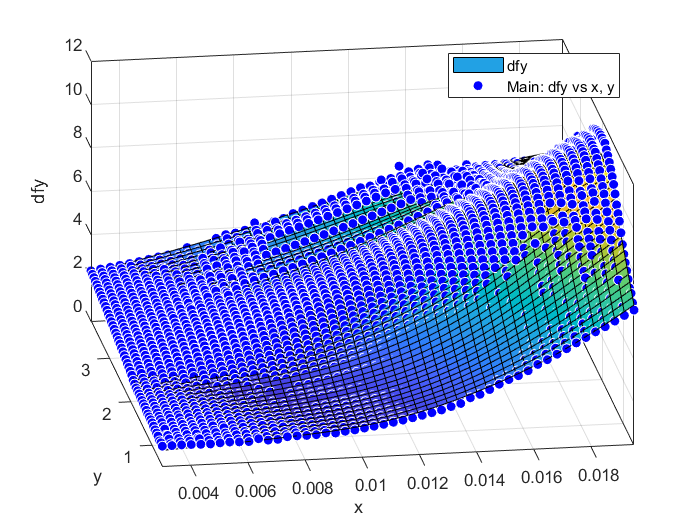

[dfy_function, ~] = createfit3D(x, y, dfy,'None',0.25,[-8.6,29.5]);